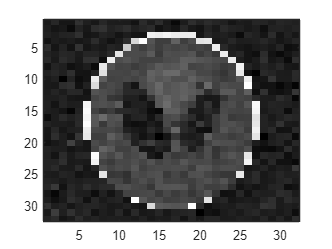

GT=phantom("modified Shepp-Logan",32);

kspace=fftshift(fft2(GT));
repetition=10;

GT_noise=add_gaussian_noise(GT,0.05,repetition);

imagesc(squeeze(real(GT_noise(1,:,:))));
colormap gray;

arranged_GT_noise=reshape(GT_noise,10,[])';

mean=sum(arranged_GT_noise,1)/(32^2);
shifted_arranged_GT_noise=arranged_GT_noise-mean;

C=cov(shifted_arranged_GT_noise);
[evector,evalue]=eig(C);


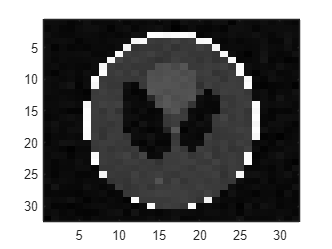

[~,index]=max(diag(evalue));
u_principal=evector(:,index);

temp=shifted_arranged_GT_noise*u_principal;
recon=temp*u_principal'+mean;

figure;
recon1=squeeze(recon(:,1));
imagesc(real(reshape(recon1,32,32)));
colormap gray;